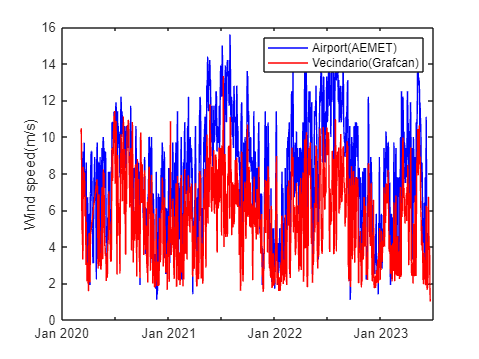

% Representar todos los datos
plot(windAEMET.date, windAEMET.avgWindSpeed, "b")
hold on
plot(dailyWindVecindario.date, dailyWindVecindario.Wind_Speed_Avg, "r")
hold off
ylabel("Wind speed(m/s)")
legend("Airport(AEMET)", "Vecindario(Grafcan)")

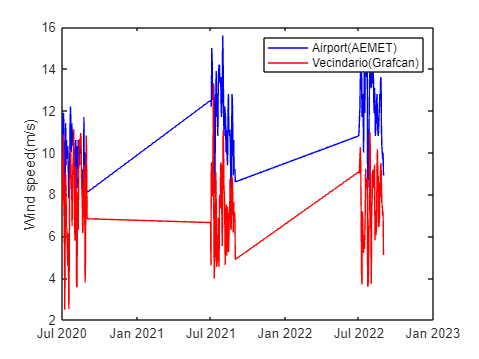

% Representar solo los meses de julio y agosto
dailyWindVecindario.monthNumber = month(dailyWindVecindario.date);
windAEMET.monthNumber = month(windAEMET.date);

plot(windAEMET.date(ismember(windAEMET.monthNumber, [7, 8])), windAEMET.avgWindSpeed(ismember(windAEMET.monthNumber, [7, 8])), "-b")
hold on
plot(dailyWindVecindario.date(ismember(dailyWindVecindario.monthNumber, [7, 8])), dailyWindVecindario.Wind_Speed_Avg(ismember(dailyWindVecindario.monthNumber, [7, 8])), "-r")
hold off
ylabel("Wind speed(m/s)")
legend("Airport(AEMET)", "Vecindario(Grafcan)")

% Extraer año y mes de los datos de la boya de Gando
vientosBoya.monthNum = month(vientosBoya.DateAtmosf);
vientosBoya.yearNum = year(vientosBoya.DateAtmosf);
vientosBoya.dayNum = day(vientosBoya.DateAtmosf);

% Comprobar si hay fechas nulas por si hay que corregir
find(isnat(vientosBoya.DateAtmosf));

% Quitar la parte de hora de la fecha
vientosBoya.dateYear = vientosBoya.DateAtmosf;
vientosBoya.dateYear.Format = "dd/MM/uuuu";

% Calcular la media 
dailyBoya = retime(table2timetable(vientosBoya), 'daily', 'mean');
dailyBoya = timetable2table(dailyBoya);

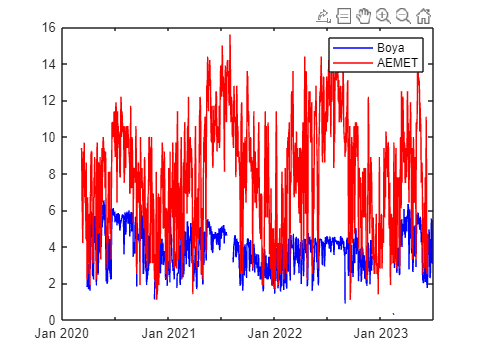

% Representar frente a los datos de AEMET
plot(dailyBoya.DateAtmosf, dailyBoya.AverageWindSpeedMs, "b")
hold on
plot(windAEMET.date, windAEMET.avgWindSpeed, "r")
hold off
legend("Boya", "AEMET")

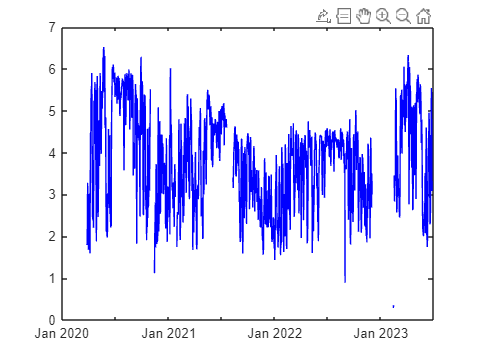

% Representar frente a los datos de Vecindario
plot(dailyBoya.DateAtmosf, dailyBoya.AverageWindSpeedMs, "b")

hold on
plot(dailyWindVecindario.date, dailyWindVecindario.Wind_Speed_Avg, "r")
hold off
legend("Boya", "Vecindario")